# Basic Information

## Overview

Transmission-line parameters extractor MATLAB implementation of Patent US8892414B1 Author Name: Guorui Wei Created in: 2020-03-15 12:45

clc; clear; close all;

## Import data

% Import simulated data
lineLength = 0.00508; % Line Length(meters)
filename_4line = 'data/4line/4lines_HFSS/4lines_HFSS_200mil.s8p';
SingleEnded8PortData = read(rfdata.data,filename_4line);
freq = SingleEnded8PortData.Freq;
freqPts = length(freq);
z0 = SingleEnded8PortData.Z0; % Reference Impedance
SingleEnded8PortData.S_Parameters = snp2smp(SingleEnded8PortData.S_Parameters,...
    z0,1:1:8); % Classic style
numOfLines = size(SingleEnded8PortData.S_Parameters,1)/2;
s_original = SingleEnded8PortData.S_Parameters;

load('test2','rlgc_PowerSI','rlgc_HFSSW');

## Extract RLGC params using proposed method

rlgc_t = s2rlgc_t(SingleEnded8PortData.S_Parameters,lineLength,freq,z0,[],false);

## Smooth data test

### R

R_noisy = squeeze(rlgc_t.R(1,2,:));

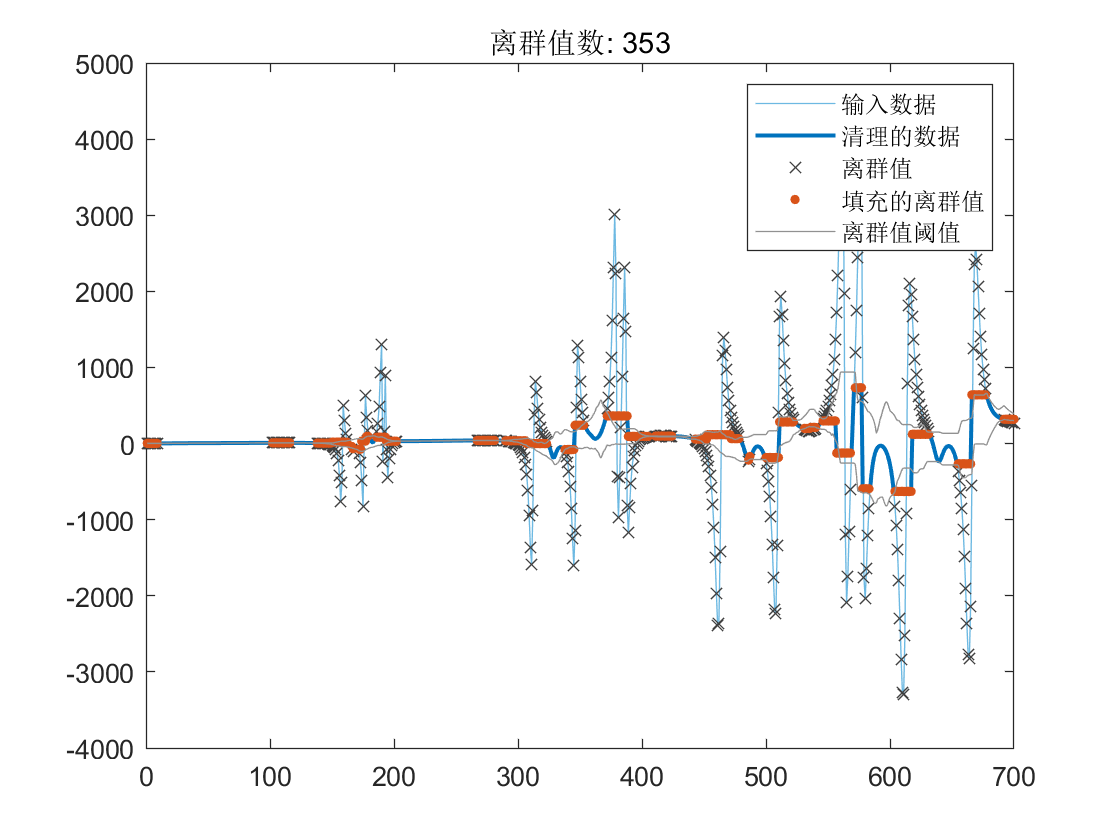

% 填充离群值
[R_cleaned,outlierIndices4,thresholdLow4,thresholdHigh4] = filloutliers(R_noisy,...
    'nearest','movmedian',50,'ThresholdFactor',0.5);

% 显示结果
clf
plot(R_noisy,'Color',[109 185 226]/255,'DisplayName','输入数据')
hold on
plot(R_cleaned,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','清理的数据')

% 绘制离群值
plot(find(outlierIndices4),R_noisy(outlierIndices4),'x','Color',[64 64 64]/255,...
    'DisplayName','离群值')
title(['离群值数: ' num2str(nnz(outlierIndices4))])

% 绘制填充的离群值
plot(find(outlierIndices4),R_cleaned(outlierIndices4),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','填充的离群值')

% 绘制离群值阈值
plot([(1:numel(R_noisy))'; missing; (1:numel(R_noisy))'],...
    [thresholdHigh4(:); missing; thresholdLow4(:)],'Color',[145 145 145]/255,...
    'DisplayName','离群值阈值')

hold off
legend

clear outlierIndices4 thresholdLow4 thresholdHigh4

### L

L_noisy = squeeze(rlgc_t.L(1,2,:));

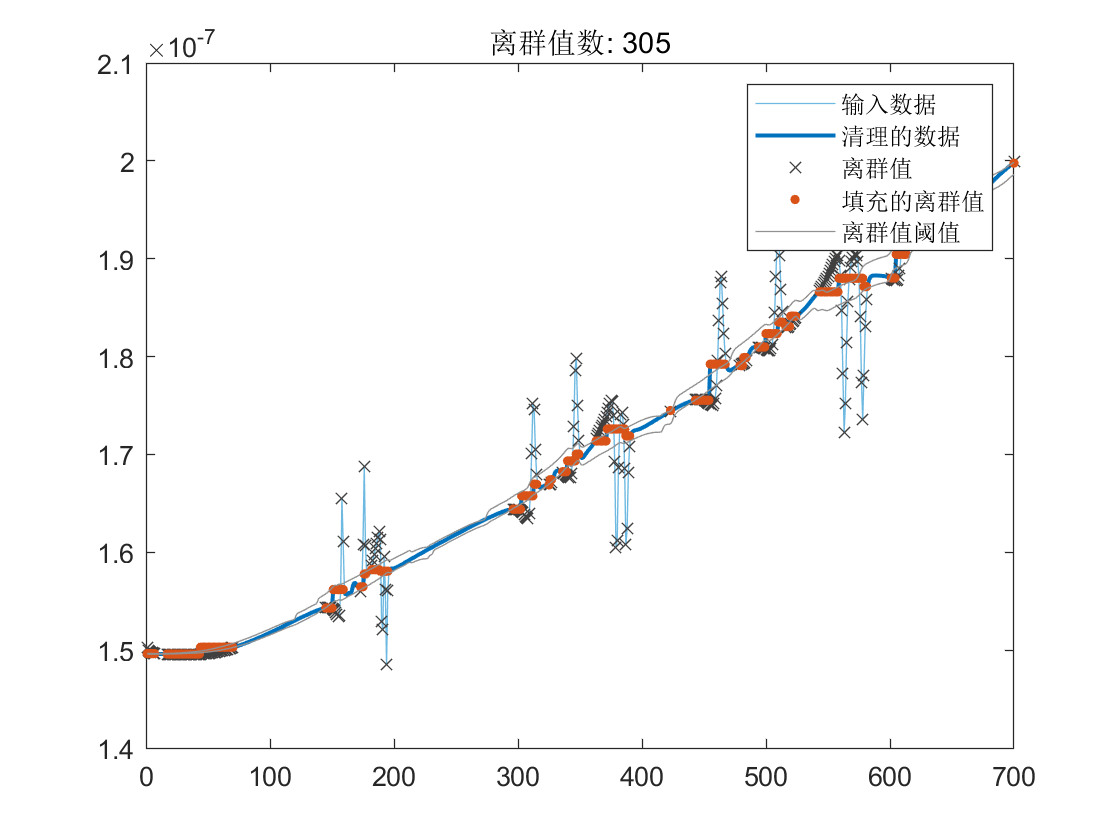

% 填充离群值
[L_cleaned,outlierIndices5,thresholdLow5,thresholdHigh5] = filloutliers(L_noisy,...
    'nearest','movmean',75,'ThresholdFactor',0.25);

% 显示结果
clf
plot(L_noisy,'Color',[109 185 226]/255,'DisplayName','输入数据')
hold on
plot(L_cleaned,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','清理的数据')

% 绘制离群值
plot(find(outlierIndices5),L_noisy(outlierIndices5),'x','Color',[64 64 64]/255,...
    'DisplayName','离群值')
title(['离群值数: ' num2str(nnz(outlierIndices5))])

% 绘制填充的离群值
plot(find(outlierIndices5),L_cleaned(outlierIndices5),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','填充的离群值')

% 绘制离群值阈值
plot([(1:numel(L_noisy))'; missing; (1:numel(L_noisy))'],...
    [thresholdHigh5(:); missing; thresholdLow5(:)],'Color',[145 145 145]/255,...
    'DisplayName','离群值阈值')

hold off
legend

clear outlierIndices5 thresholdLow5 thresholdHigh5

### G

G_noisy = squeeze(rlgc_t.G(1,2,:));

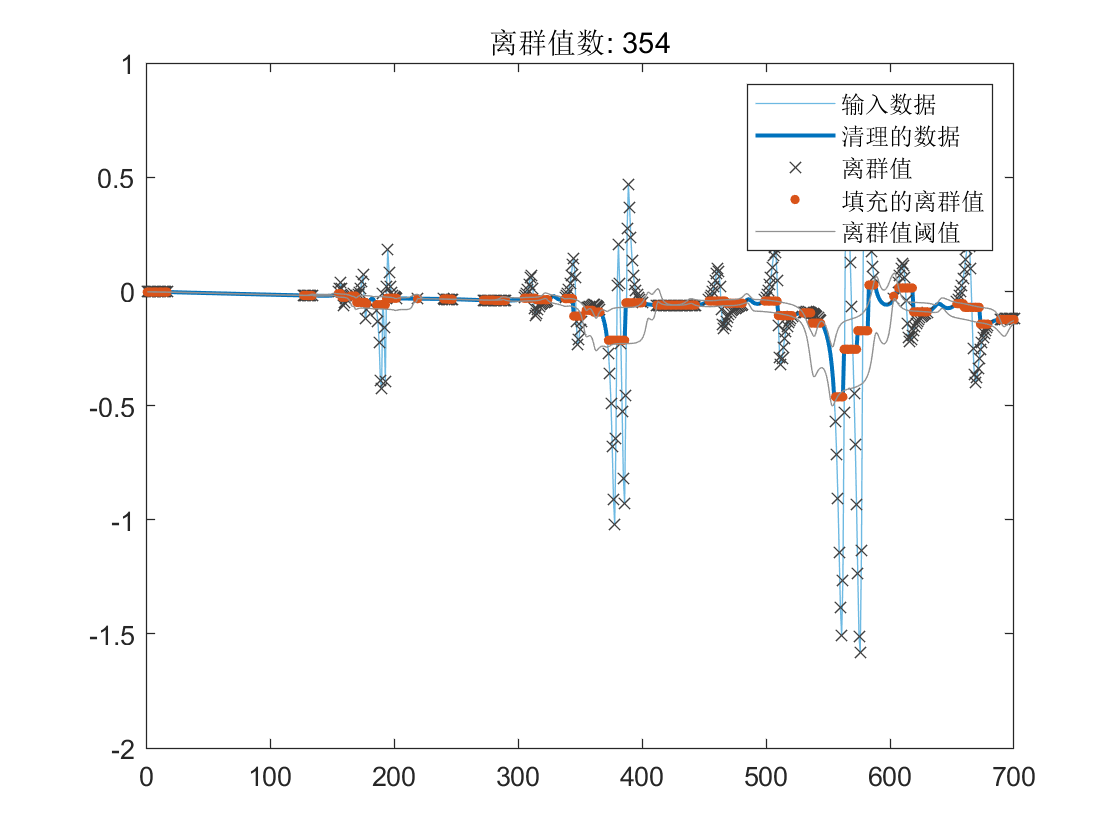

% 填充离群值
[G_cleaned,outlierIndices2,thresholdLow2,thresholdHigh2] = filloutliers(G_noisy,...
    'nearest','movmean',50,'ThresholdFactor',0.25);

% 显示结果
clf
plot(G_noisy,'Color',[109 185 226]/255,'DisplayName','输入数据')
hold on
plot(G_cleaned,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','清理的数据')

% 绘制离群值
plot(find(outlierIndices2),G_noisy(outlierIndices2),'x','Color',[64 64 64]/255,...
    'DisplayName','离群值')
title(['离群值数: ' num2str(nnz(outlierIndices2))])

% 绘制填充的离群值
plot(find(outlierIndices2),G_cleaned(outlierIndices2),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','填充的离群值')

% 绘制离群值阈值
plot([(1:numel(G_noisy))'; missing; (1:numel(G_noisy))'],...
    [thresholdHigh2(:); missing; thresholdLow2(:)],'Color',[145 145 145]/255,...
    'DisplayName','离群值阈值')

hold off
legend

clear outlierIndices2 thresholdLow2 thresholdHigh2

### C

C_noisy = squeeze(rlgc_t.C(1,2,:));

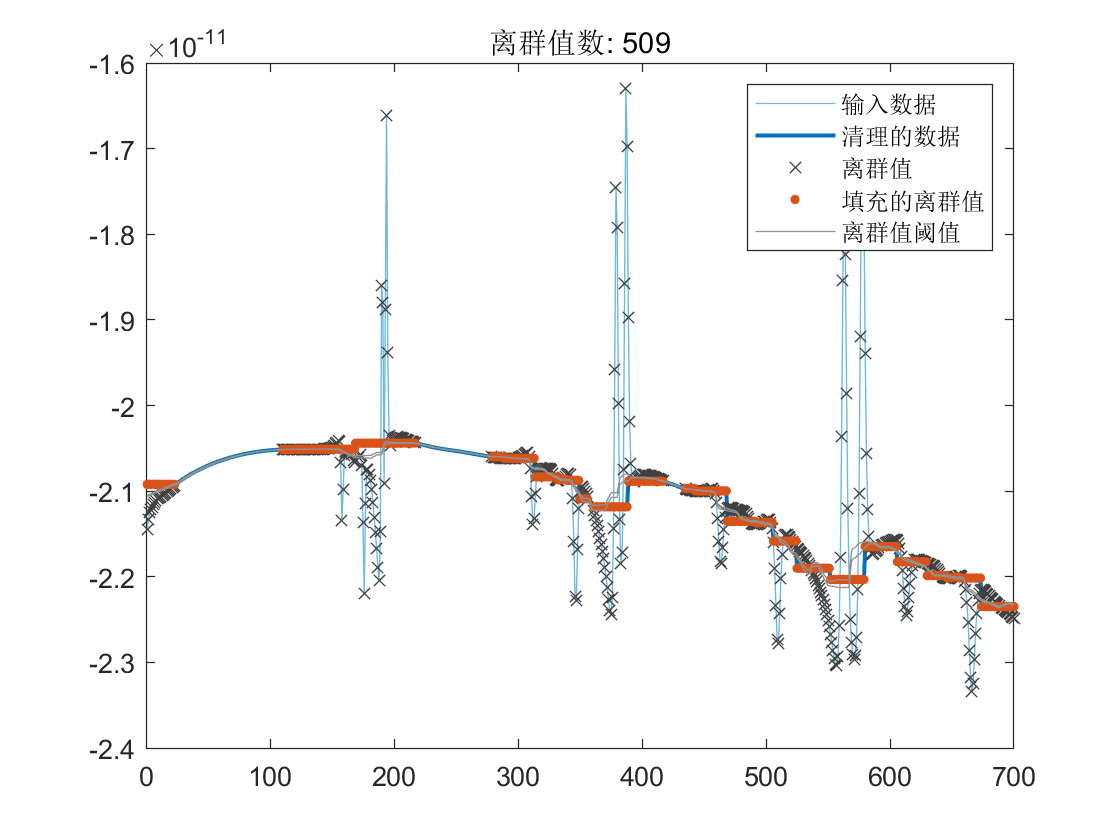

% 填充离群值
[C_cleaned,outlierIndices3,thresholdLow3,thresholdHigh3] = filloutliers(C_noisy,...
    'nearest','movmedian',50,'ThresholdFactor',0.05);

% 显示结果
clf
plot(C_noisy,'Color',[109 185 226]/255,'DisplayName','输入数据')
hold on
plot(C_cleaned,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','清理的数据')

% 绘制离群值
plot(find(outlierIndices3),C_noisy(outlierIndices3),'x','Color',[64 64 64]/255,...
    'DisplayName','离群值')
title(['离群值数: ' num2str(nnz(outlierIndices3))])

% 绘制填充的离群值
plot(find(outlierIndices3),C_cleaned(outlierIndices3),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','填充的离群值')

% 绘制离群值阈值
plot([(1:numel(C_noisy))'; missing; (1:numel(C_noisy))'],...
    [thresholdHigh3(:); missing; thresholdLow3(:)],'Color',[145 145 145]/255,...
    'DisplayName','离群值阈值')

hold off
legend

clear outlierIndices3 thresholdLow3 thresholdHigh3

## Smooth RLGC

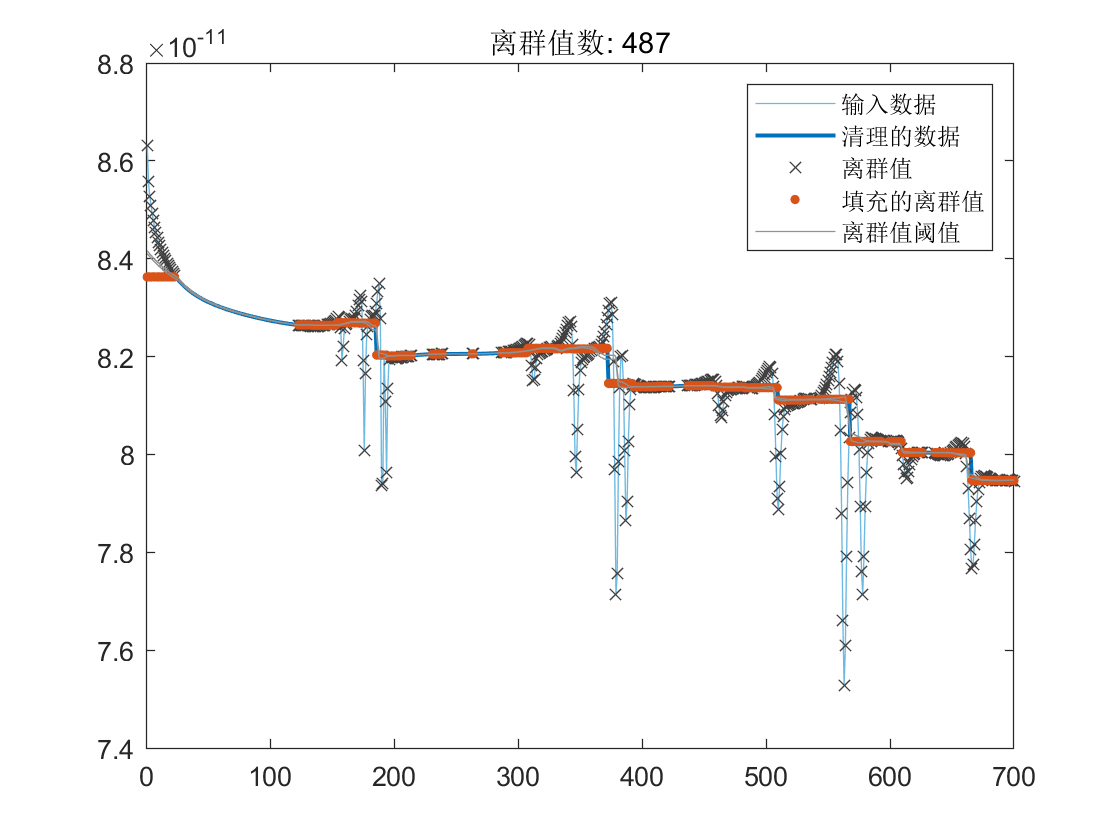

for i = numOfLines:-1:1
    for j = numOfLines:-1:i
        rlgc_smooth.R(i,j,:) = Rsmooth(rlgc_t.R(i,j,:));
        rlgc_smooth.L(i,j,:) = Lsmooth(rlgc_t.L(i,j,:));
        rlgc_smooth.G(i,j,:) = Gsmooth(rlgc_t.G(i,j,:));
        rlgc_smooth.C(i,j,:) = Csmooth(rlgc_t.C(i,j,:));
    end
end


for i = numOfLines:-1:1
    for j = numOfLines:-1:i+1
        rlgc_smooth.R(j,i,:) = rlgc_smooth.R(i,j,:);
        rlgc_smooth.L(j,i,:) = rlgc_smooth.L(i,j,:);
        rlgc_smooth.G(j,i,:) = rlgc_smooth.G(i,j,:);
        rlgc_smooth.C(j,i,:) = rlgc_smooth.C(i,j,:);
    end
end

% rlgc_smooth -> s_rlgc_smooth
[s_rlgc_smooth,~] = rlgc2s_t(rlgc_smooth.R,rlgc_smooth.L,rlgc_smooth.G,rlgc_smooth.C,lineLength,freq,z0);

## Comparison between smooth-S (dB) and original-S

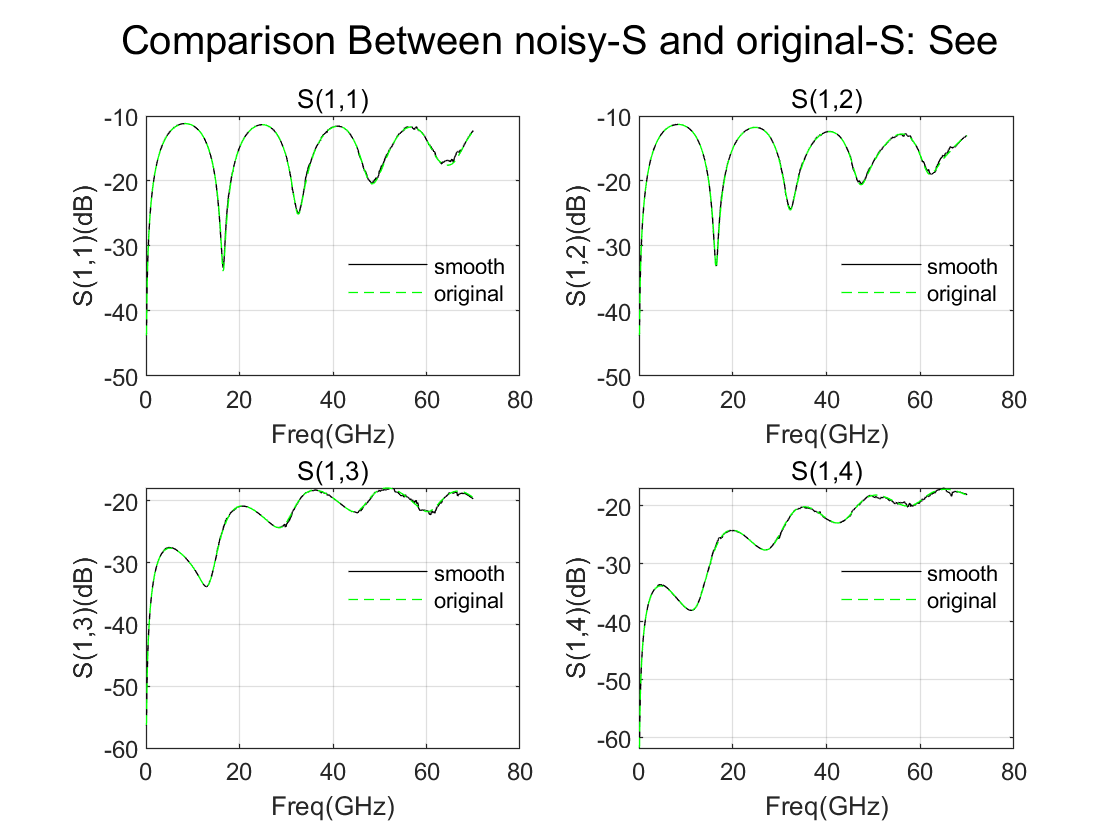

% external<-external
figure('Name','noisy-S (dB): See') 
sgtitle({'Comparison Between noisy-S and original-S: See'})
num_of_columes = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,num_of_columes,idx)
    plot(freq/1e9,db(squeeze(s_rlgc_smooth(1,idx,:)),'voltage'),'k-')
    hold on
    plot(freq/1e9,db(squeeze(s_original(1,idx,:)),'voltage'),'g--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('S(1,%u)(dB)',idx));
    title(sprintf('S(1,%u)',idx));
    legend({'smooth','original'},'Location','best','NumColumns',1)
    legend('boxoff')
end

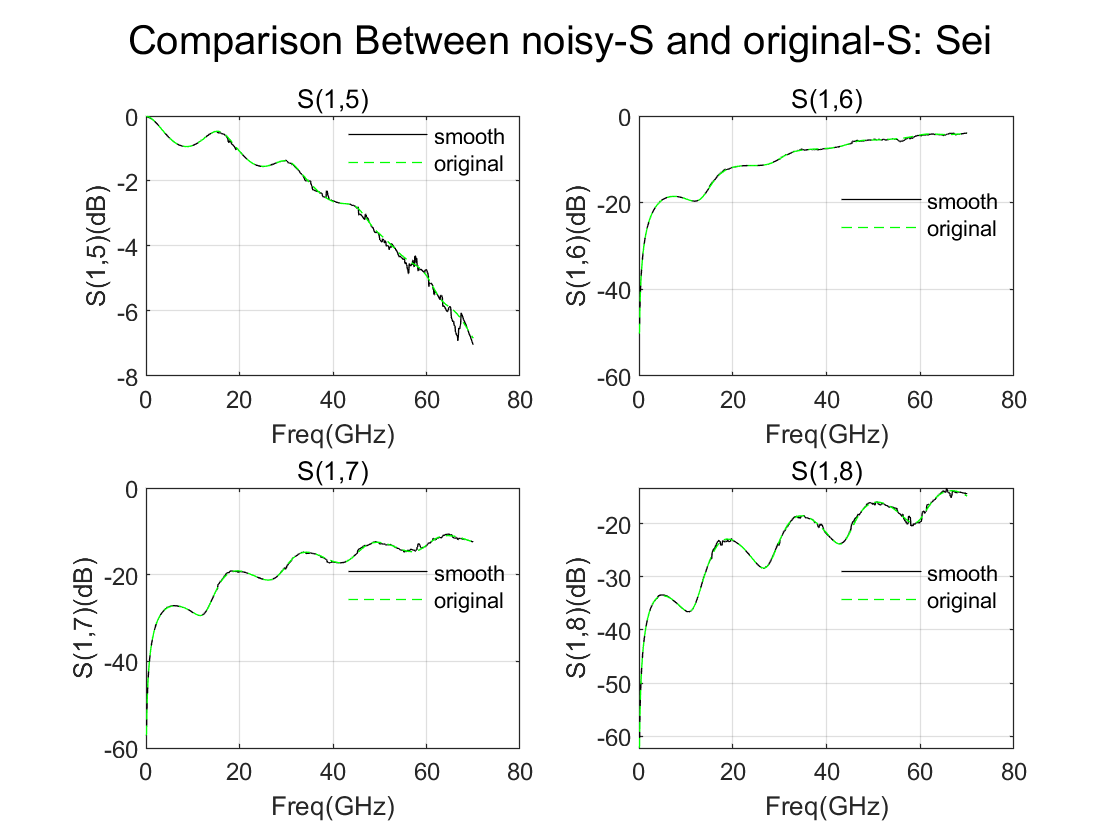


% external<-internal
figure('Name','noisy-S (dB): Sei')
sgtitle({'Comparison Between noisy-S and original-S: Sei'})
num_of_columes = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,num_of_columes,idx)
    plot(freq/1e9,db(squeeze(s_rlgc_smooth(1,idx+numOfLines,:)),'voltage'),'k-')
    hold on
    plot(freq/1e9,db(squeeze(s_original(1,idx+numOfLines,:)), 'voltage'),'g--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('S(1,%u)(dB)',idx+numOfLines));
    title(sprintf('S(1,%u)',idx+numOfLines));
    legend({'smooth','original'},'Location','best','NumColumns',1)
    legend('boxoff')
end

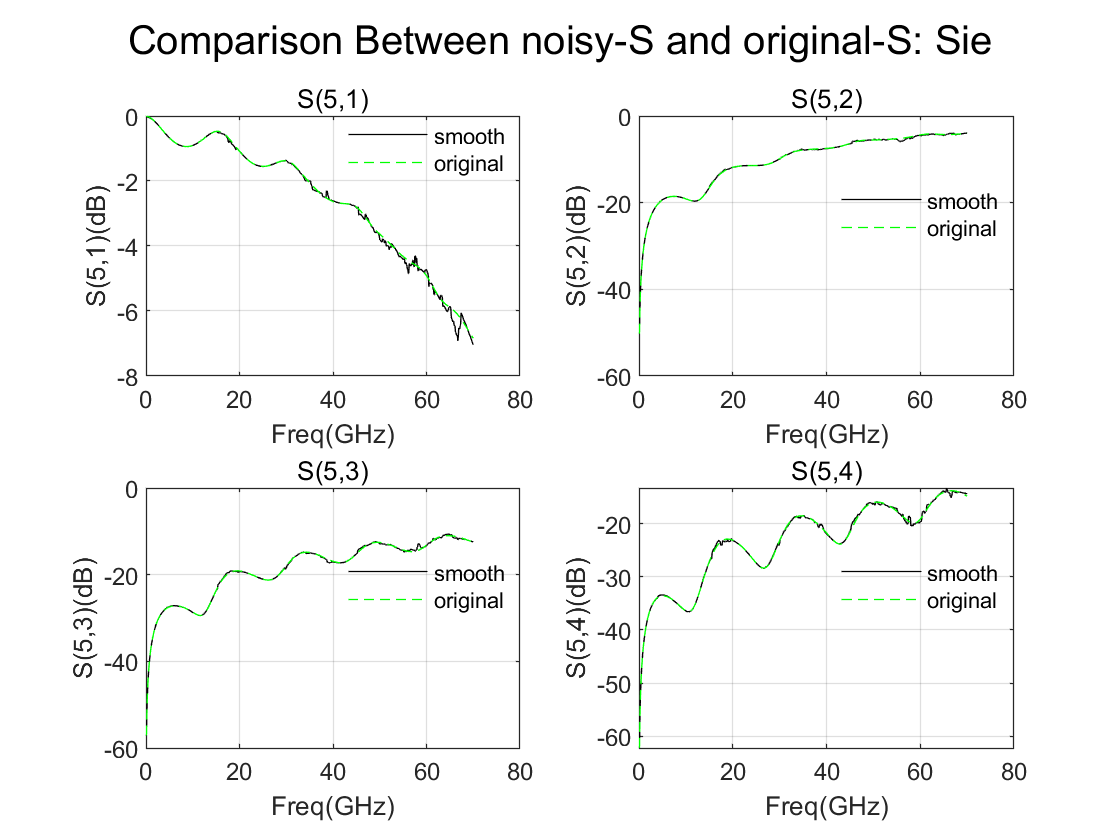


% internal<-external
figure('Name','noisy-S (dB): Sie') 
sgtitle({'Comparison Between noisy-S and original-S: Sie'})
num_of_columes = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,num_of_columes,idx)
    plot(freq/1e9,db(squeeze(s_rlgc_smooth(numOfLines+1,idx,:)),'voltage'),'k-')
    hold on
    plot(freq/1e9,db(squeeze(s_original(numOfLines+1,idx,:)),'voltage'),'g--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('S(%u,%u)(dB)',numOfLines+1,idx));
    title(sprintf('S(%u,%u)',numOfLines+1,idx));
    legend({'smooth','original'},'Location','best','NumColumns',1)
    legend('boxoff')
end

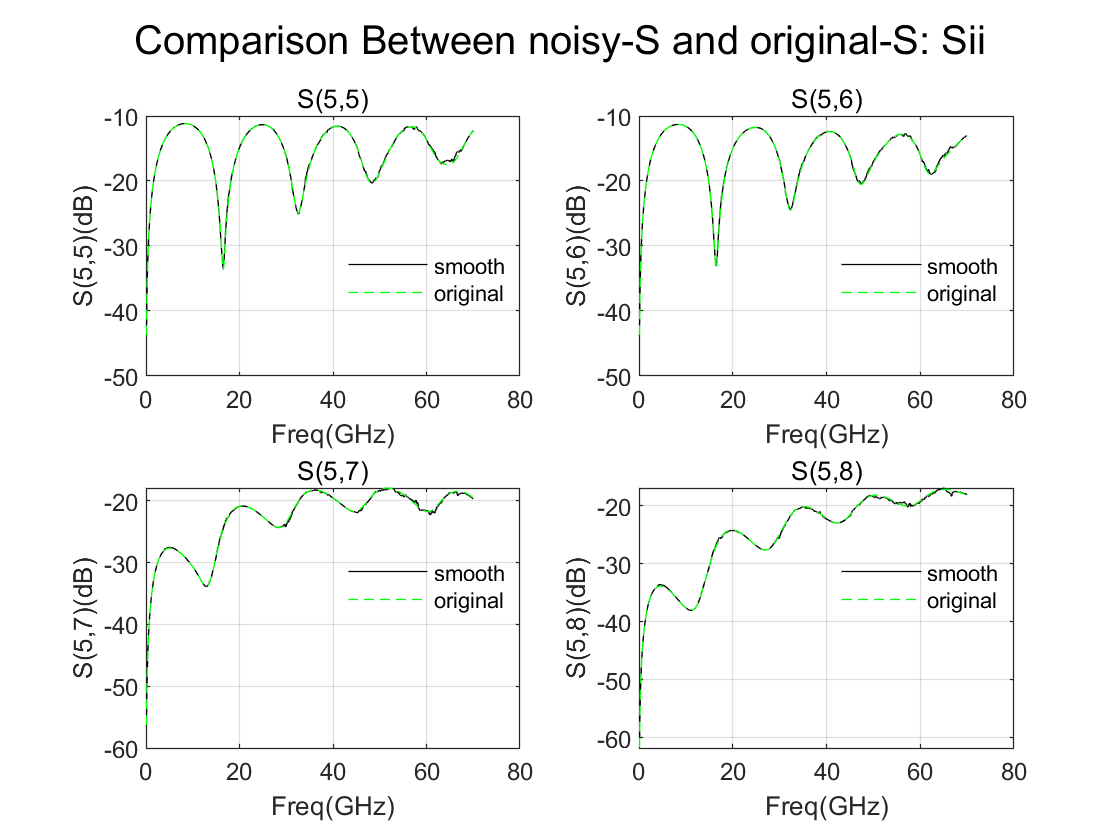


% internal<-internal
figure('Name','noisy-S (dB): Sii') 
sgtitle({'Comparison Between noisy-S and original-S: Sii'})
num_of_columes = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,num_of_columes,idx)
    plot(freq/1e9,db(squeeze(s_rlgc_smooth(numOfLines+1,numOfLines+idx,:)),'voltage'),'k-')
    hold on
    plot(freq/1e9,db(squeeze(s_original(numOfLines+1,numOfLines+idx,:)),'voltage'),'g--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('S(%u,%u)(dB)',numOfLines+1,numOfLines+idx));
    title(sprintf('S(%u,%u)',numOfLines+1,numOfLines+idx));
    legend({'smooth','original'},'Location','best','NumColumns',1)
    legend('boxoff')
end

## smooth-RLGC compared with Cadence PowerSI, HFSS

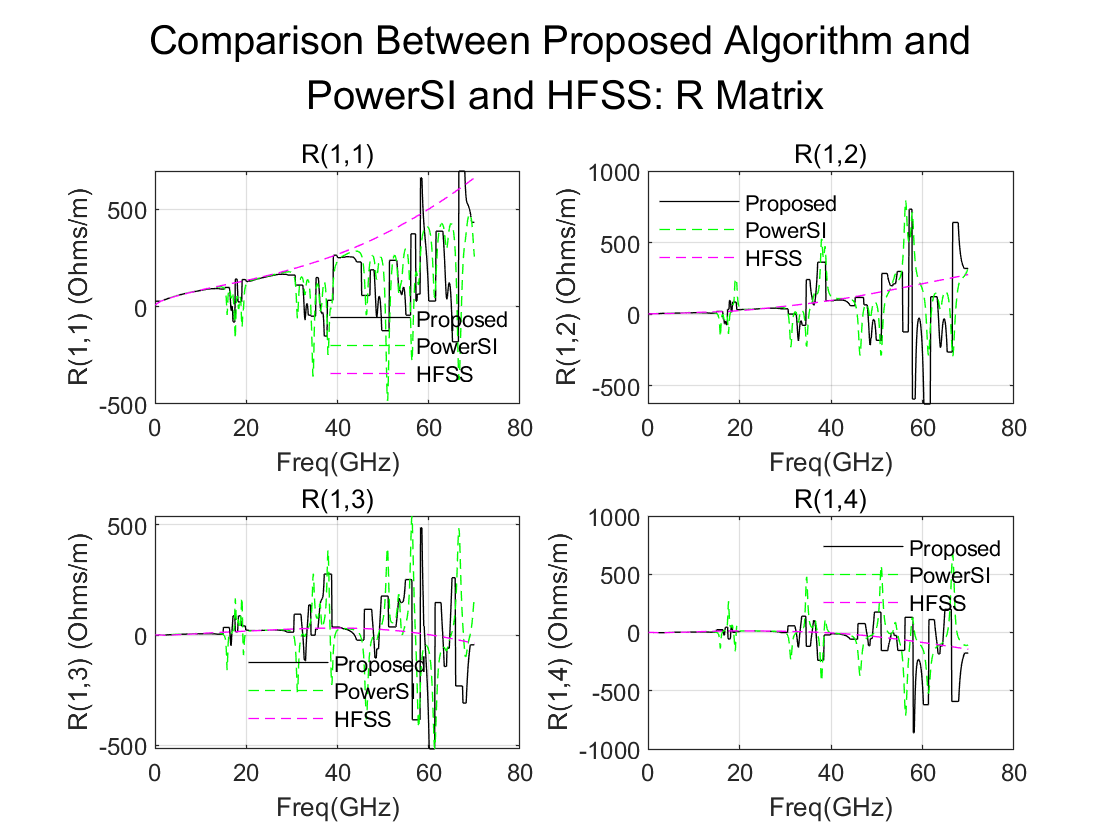

% R
figure('Name','R (compared with PowerSI, HFSS)')
sgtitle({'Comparison Between Proposed Algorithm and';' PowerSI and HFSS: R Matrix'})
total = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,total,idx)
    plot(freq/1e9,squeeze(rlgc_smooth.R(1,idx,:)),'k-')
    hold on
    plot(freq/1e9,squeeze(rlgc_PowerSI.R(1,idx,:)),'g--')
    plot(freq/1e9,squeeze(rlgc_HFSSW.R(1,idx,:)),'m--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('R(1,%u) (Ohms/m)',idx));
    title(sprintf('R(1,%u)',idx));
    legend({'Proposed','PowerSI','HFSS'},'Location','best','NumColumns',1)
    legend('boxoff')
end

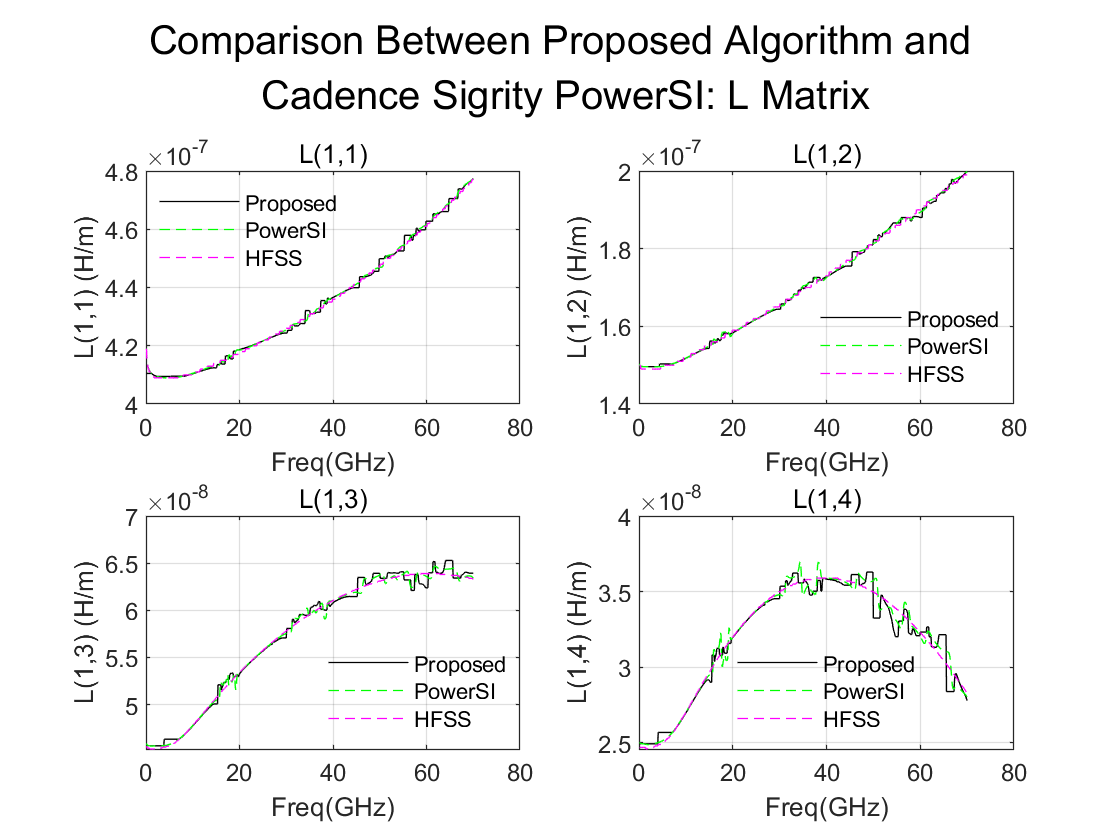


% L
figure('Name','L (compared with PowerSI, HFSS)')
sgtitle({'Comparison Between Proposed Algorithm and';' Cadence Sigrity PowerSI: L Matrix'})
total = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,total,idx)
    plot(freq/1e9,squeeze(rlgc_smooth.L(1,idx,:)),'k-')
    hold on
    plot(freq/1e9,squeeze(rlgc_PowerSI.L(1,idx,:)),'g--')
    plot(freq/1e9,squeeze(rlgc_HFSSW.L(1,idx,:)),'m--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('L(1,%u) (H/m)',idx));
    title(sprintf('L(1,%u)',idx));
    legend({'Proposed','PowerSI','HFSS'},'Location','best','NumColumns',1)
    legend('boxoff')
end

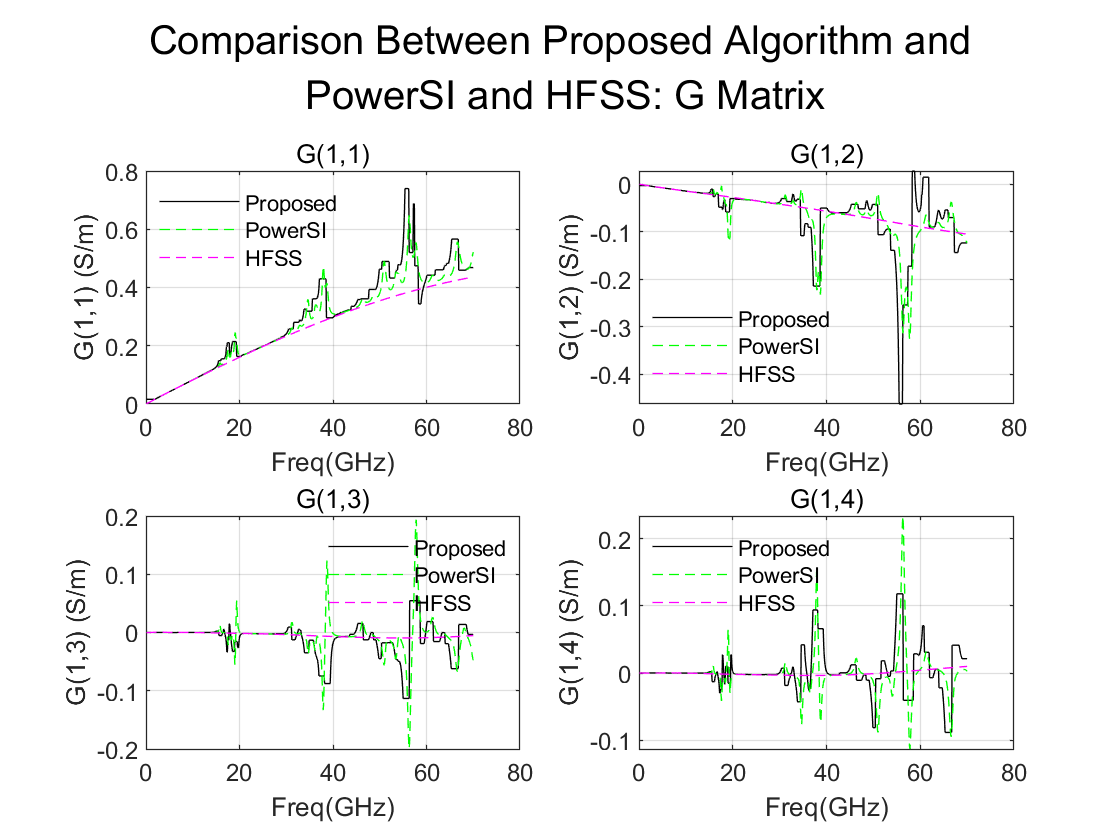


% G
figure('Name','G (compared with PowerSI, HFSS)')
sgtitle({'Comparison Between Proposed Algorithm and';' PowerSI and HFSS: G Matrix'})
total = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,total,idx)
    plot(freq/1e9,squeeze(rlgc_smooth.G(1,idx,:)),'k-')
    hold on
    plot(freq/1e9,squeeze(rlgc_PowerSI.G(1,idx,:)),'g--')
    plot(freq/1e9,squeeze(rlgc_HFSSW.G(1,idx,:)),'m--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('G(1,%u) (S/m)',idx));
    title(sprintf('G(1,%u)',idx));
    legend({'Proposed','PowerSI','HFSS'},'Location','best','NumColumns',1)
    legend('boxoff')
end

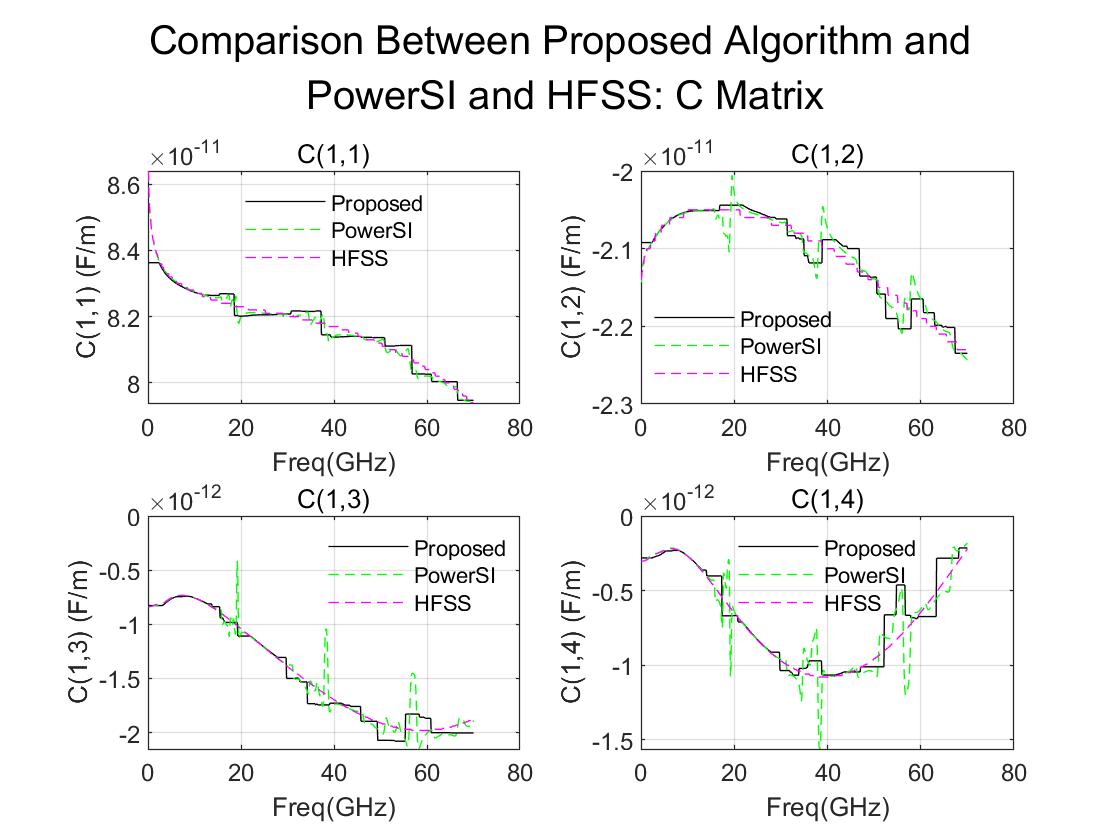


% C
figure('Name','C (compared with PowerSI, HFSS)')
sgtitle({'Comparison Between Proposed Algorithm and';' PowerSI and HFSS: C Matrix'})
total = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,total,idx)
    plot(freq/1e9,squeeze(rlgc_smooth.C(1,idx,:)),'k-')
    hold on
    plot(freq/1e9,squeeze(rlgc_PowerSI.C(1,idx,:)),'g--')
    plot(freq/1e9,squeeze(rlgc_HFSSW.C(1,idx,:)),'m--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('C(1,%u) (F/m)',idx));
    title(sprintf('C(1,%u)',idx));
    legend({'Proposed','PowerSI','HFSS'},'Location','best','NumColumns',1)
    legend('boxoff')
end

### R smooth

function [R_cleaned] = Rsmooth(R_noisy)

R_noisy = squeeze(R_noisy);

% 填充离群值
[R_cleaned,outlierIndices4,thresholdLow4,thresholdHigh4] = filloutliers(R_noisy,...
    'nearest','movmedian',50,'ThresholdFactor',0.5);

% 显示结果
clf
plot(R_noisy,'Color',[109 185 226]/255,'DisplayName','输入数据')
hold on
plot(R_cleaned,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','清理的数据')

% 绘制离群值
plot(find(outlierIndices4),R_noisy(outlierIndices4),'x','Color',[64 64 64]/255,...
    'DisplayName','离群值')
title(['离群值数: ' num2str(nnz(outlierIndices4))])

% 绘制填充的离群值
plot(find(outlierIndices4),R_cleaned(outlierIndices4),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','填充的离群值')

% 绘制离群值阈值
plot([(1:numel(R_noisy))'; missing; (1:numel(R_noisy))'],...
    [thresholdHigh4(:); missing; thresholdLow4(:)],'Color',[145 145 145]/255,...
    'DisplayName','离群值阈值')

hold off
legend
clear outlierIndices4 thresholdLow4 thresholdHigh4

end

### L smooth

function [L_cleaned] = Lsmooth(L_noisy)

L_noisy = squeeze(L_noisy);

% 填充离群值
[L_cleaned,outlierIndices5,thresholdLow5,thresholdHigh5] = filloutliers(L_noisy,...
    'nearest','movmean',75,'ThresholdFactor',0.25);

% 显示结果
clf
plot(L_noisy,'Color',[109 185 226]/255,'DisplayName','输入数据')
hold on
plot(L_cleaned,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','清理的数据')

% 绘制离群值
plot(find(outlierIndices5),L_noisy(outlierIndices5),'x','Color',[64 64 64]/255,...
    'DisplayName','离群值')
title(['离群值数: ' num2str(nnz(outlierIndices5))])

% 绘制填充的离群值
plot(find(outlierIndices5),L_cleaned(outlierIndices5),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','填充的离群值')

% 绘制离群值阈值
plot([(1:numel(L_noisy))'; missing; (1:numel(L_noisy))'],...
    [thresholdHigh5(:); missing; thresholdLow5(:)],'Color',[145 145 145]/255,...
    'DisplayName','离群值阈值')

hold off
legend
clear outlierIndices5 thresholdLow5 thresholdHigh5

end

### G smooth

function [G_cleaned] = Gsmooth(G_noisy)

G_noisy = squeeze(G_noisy);

% 填充离群值
[G_cleaned,outlierIndices,thresholdLow,thresholdHigh] = filloutliers(G_noisy,...
    'nearest','movmean',50,'ThresholdFactor',0.25);

% 显示结果
clf
plot(G_noisy,'Color',[109 185 226]/255,'DisplayName','输入数据')
hold on
plot(G_cleaned,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','清理的数据')

% 绘制离群值
plot(find(outlierIndices),G_noisy(outlierIndices),'x','Color',[64 64 64]/255,...
    'DisplayName','离群值')
title(['离群值数: ' num2str(nnz(outlierIndices))])

% 绘制填充的离群值
plot(find(outlierIndices),G_cleaned(outlierIndices),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','填充的离群值')

% 绘制离群值阈值
plot([(1:numel(G_noisy))'; missing; (1:numel(G_noisy))'],...
    [thresholdHigh(:); missing; thresholdLow(:)],'Color',[145 145 145]/255,...
    'DisplayName','离群值阈值')

hold off
legend
clear outlierIndices thresholdLow thresholdHigh

end

### C smooth

function [C_cleaned] = Csmooth(C_noisy)

C_noisy = squeeze(C_noisy);

% 填充离群值
[C_cleaned,outlierIndices6,thresholdLow6,thresholdHigh6] = filloutliers(C_noisy,...
    'nearest','movmedian',50,'ThresholdFactor',0.05);

% 显示结果
clf
plot(C_noisy,'Color',[109 185 226]/255,'DisplayName','输入数据')
hold on
plot(C_cleaned,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','清理的数据')

% 绘制离群值
plot(find(outlierIndices6),C_noisy(outlierIndices6),'x','Color',[64 64 64]/255,...
    'DisplayName','离群值')
title(['离群值数: ' num2str(nnz(outlierIndices6))])

% 绘制填充的离群值
plot(find(outlierIndices6),C_cleaned(outlierIndices6),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','填充的离群值')

% 绘制离群值阈值
plot([(1:numel(C_noisy))'; missing; (1:numel(C_noisy))'],...
    [thresholdHigh6(:); missing; thresholdLow6(:)],'Color',[145 145 145]/255,...
    'DisplayName','离群值阈值')

hold off
legend
clear outlierIndices6 thresholdLow6 thresholdHigh6

end